# Advection-diffusion equation in 2D

## 1. Case description

We want to numerically solve with the Finite Difference (FDM) method the advection-diffusion equation in 2D, over a rectangular domain with size $L_x \times L_y$:


$$\frac{\partial f}{\partial t}+u\frac{\partial f}{\partial x}+v\frac{\partial f}{\partial y}=\Gamma \left(\frac{\partial^2 f}{\partial x^2 }+\frac{\partial^2 f}{\partial y^2 }\right)$$


Along the north $\left(y=L_y \right)$, south $\left(y=0\right)$, and west $\left(x=0\right)$ sides, zero gradient boundary conditions (i.e. Neumann's boundary conditions) are prescribed:


$$\frac{\partial f}{\partial n}=0$$


where $n$ is the normal direction to the boundary. Along the east side $\left(x=L_x \right)$, the following Dirichlet boundary conditions are prescribed:


$$f\left(x=L_x ;y\in \left\lbrack \frac{L_y }{3};\frac{{2L}_y }{3}\right\rbrack \right)=f_{\mathrm{inlet}}$$



$$f\left(x=L_x ;y\in \left\lbrack 0;\frac{L_y }{3}\right\rbrack \cup \left\lbrack \frac{{2L}_y }{3};L_y \right\rbrack \right)=0$$


We are going to use the **explicit (or forward) Euler method** in time, while for spatial discretization of advective and diffusive terms **centered, 2nd order discretizations**. We assume constant, uniform velocities $u$ and $v$ and diffusion coefficient $\Gamma$. The discretized equation becomes:


$$\frac{f_{i,j}^{n+1} -f_{i,j}^n }{\Delta t}+u\frac{f_{i+1,j}^n -f_{i-1,j}^n }{2h_x }+v\frac{f_{i,j+1}^n -f_{i,j-1}^n }{2h_y }=\Gamma \frac{f_{i+1,j}^n -2f_{i,j}^n +f_{i-1,j}^n }{h_x^2 }+\Gamma \frac{f_{i,j+1}^n -2f_{i,j}^n +f_{i,j-1}^n }{h_y^2 }$$


The image below reports the typical solution after a sufficiently large time on a squared grid. Notice the Dirichlet boundary conditions along the east side $\left(x=L_x \right)$.

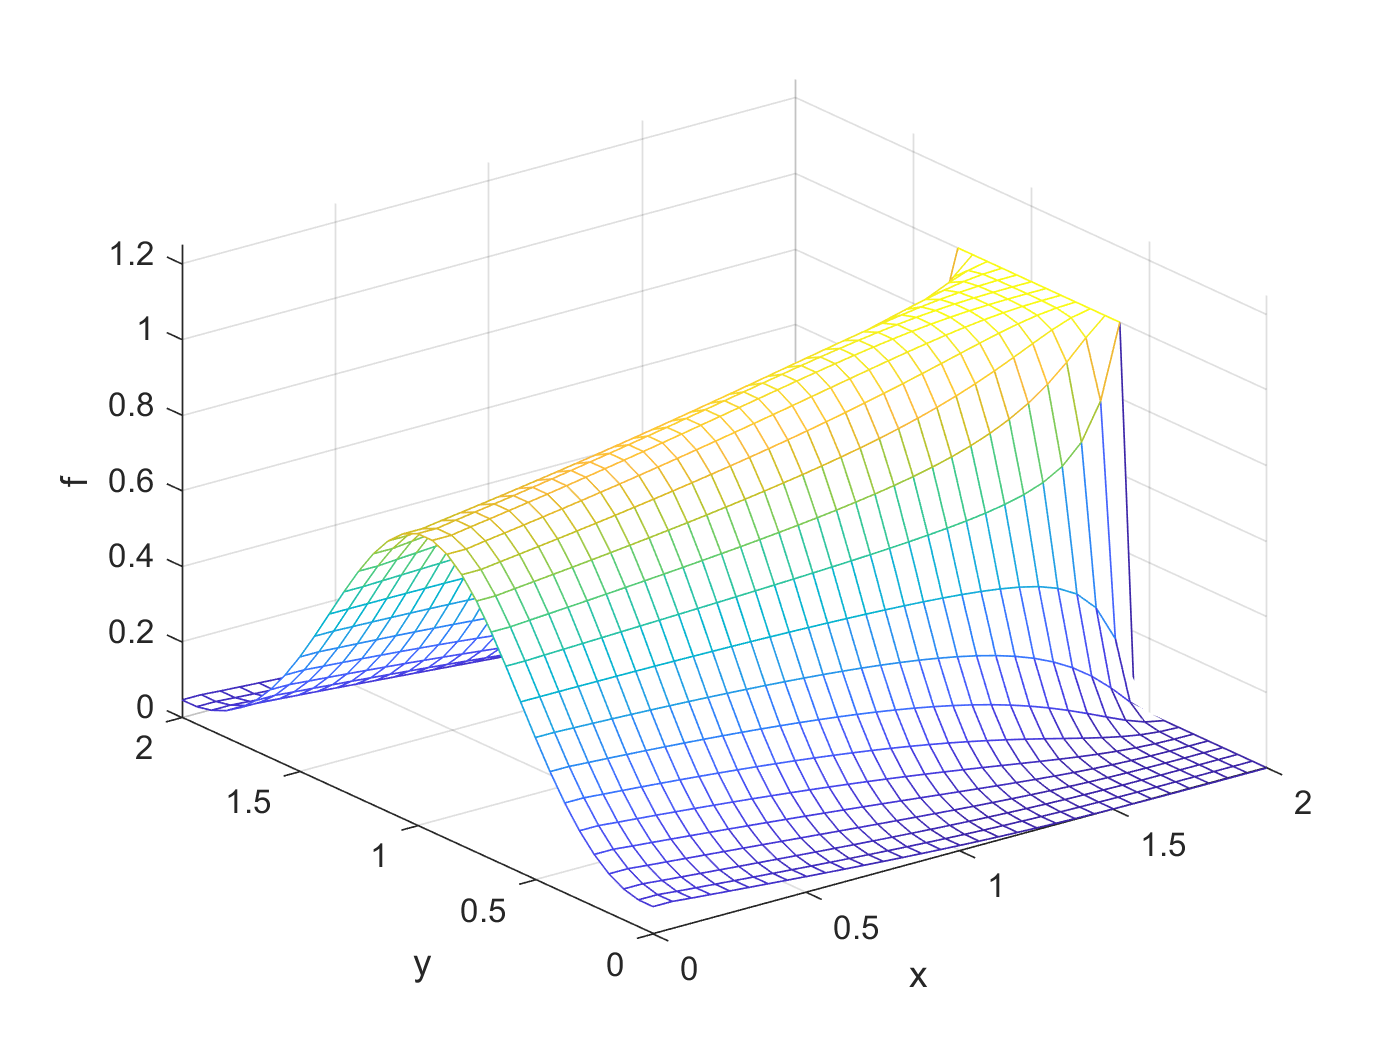

## 2. Implementation

### a. Numerical setup

As a first example we consider a regular 2D squared grid $\left(L_x =L_y \right)$, with same number of points along the two directions $\left(n_x =n_y \right)$. We also assign the diffusion coefficient (constant and uniform) and the velocity fiels, i.e. the 2 components $u$ and $v$. In particular, we impose $u=-1$ and $v=0$, which physically correspond to a uniform and constant velocity field parallel to the x axis, from east to west side. The inlet value of $f$ variable is also fixed as $f_{\mathrm{inlet}}$.

From the physical point of view, we are studying the advection and diffusion of a scalar $f$ which enters from the central section of the east side (see boundary conditions reported above). It is transported along the horizontal (i.e. parallel to x axis) direction because of advection and diffuses along both directions because of diffusion.

We calculate now the spatial steps $h_x$ and $h_y$:

The time step is chosen according to the stability conditions on advection and diffusion, including a safety coefficient $\sigma$:


$$\Delta t\le \sigma \;\mathrm{min}\left(\frac{4\Gamma }{u^2 +v^2 },\frac{1}{4}\frac{h_x h_y }{\Gamma }\right)$$


In order to ensure a good computational efficiency, it is convenient to pre-allocate memory for the relevant vectors $f$ (new solution at time $n+1$) and $f^{old}$ (old solution at time $n$):

Notice that with the instructions above not only we allocated memory, but we also set the two fields equal to zero.

Let's fix the boundary conditions along the inlet section:

There is no need to set explicitly the second BC, since the $f$field has been automatically set equal to 0 everywhere.

### b. Advancing the solution in time

We can now proceed with the numerical solution, advancing in time, starting from $t=0$. Let's apply the forward Euler method over all the internal points:


$$f_{i,j}^{n+1} =f_{i,j}^n -\frac{u\Delta t}{2h_x }\left(f_{i+1,j}^n -f_{i-1,j}^n \right)-\frac{v\Delta t}{2h_y }\left(f_{i,j+1}^n -f_{i,j-1}^n \right)+\frac{\Gamma \Delta t}{h_x^2 }\left(f_{i+1,j}^n -2f_{i,j}^n +f_{i-1,j}^n \right)+\frac{\Gamma \Delta t}{h_y^2 }\left(f_{i,j+1}^n -2f_{i,j}^n +f_{i,j-1}^n \right)$$


The corresponding code is reported in the following:

We then apply the Neumann's boundary conditions along the south, north, and west sides:

There is no need to apply explicitly the boundary conditions along the east side, because they have been already fixed (they are steady-state Dirichlet boundary conditions). Only in case of Dirichlet boundary conditions changing in time, it would be necessary update them.

We can now advance to the next time level:

### c. Graphical output

Before starting the calculation, we prepare and open a video stream to register the evolution of the solution in time:

For graphical purposes only, it is convenient to define two vectors corresponding to the grid points in the two directions:

At each time step it is convenient to plot the surface corresponding to the current solution:

At the end of the calculations we have to close the video stream:

## 3. Bringing it All Together

Let's bring it all together.

% Cleaning the MATLAB environment
%-------------------------------------------------------------------------%
close all;
clear variables;

% User-defined data
%-------------------------------------------------------------------------%
nx=33;                  % number of grid points along x
ny=33;                  % number of grid points along y
nstep=150;              % number of time steps
lengthx=2.0;            % domain length along x [m]
lengthy=2.0;            % domain length along y [m]
D=0.025;                % diffusion coefficient [m2/s]
u=-1;                   % velocity along x [m/s]
v= 0;                   % velocity along y [m/s]
fin=1;                  % inlet value of f

% Pre-processing of user-defined data
%-------------------------------------------------------------------------%
% Calculate grid steps
hx=lengthx/(nx-1);      % grid step along x [m]
hy=lengthy/(ny-1);      % grid step along y [m] 

% Numerical setup: time step (stability conditions)
sigma = 0.75;                     % safety coefficient
dt_diff  = 1/4*hx*hy/D;           % diffusion [s]
dt_conv = 4*D/(u^2+v^2);          % convection [s]
dt = sigma*min(dt_diff, dt_conv); % time step [s]

% Memory allocation
f=zeros(nx,ny);     % current numerical solution
fo=zeros(nx,ny);    % previous numerical solution

% Dirichlet boundary conditions along the east side
f(nx, ny*1/3:ny*2/3) = fin;

% Definition of rectangular mesh (graphical purposes only)
xaxis = 0:hx:lengthx;
yaxis = 0:hy:lengthy;

% Video setup
%-------------------------------------------------------------------------%
video_name = 'advection_diffusion_2d.mp4';
videompg4 = VideoWriter(video_name, 'MPEG-4');
open(videompg4);

% Advancing in time
%-------------------------------------------------------------------------%
t = 0.;
for m=1:nstep
    
    % Plot the current solution
    hold off; 
    mesh(xaxis, yaxis, f'); 
    axis([0 lengthx 0 lengthy 0 1.25]);
    xlabel('x'); ylabel('y'); zlabel('f');
    message = sprintf('time=%d\n', t);
    time = annotation('textbox',[0.15 0.8 0.15 0.15],'String',message,'EdgeColor','none');
    frame = getframe(gcf);
    writeVideo(videompg4,frame);
    delete(time); 

    % Forward Euler method
    fo=f;
    for i=2:nx-1
        for j=2:ny-1
            f(i,j) = fo(i,j)...
                    -(0.5*dt*u/hx)*(fo(i+1,j)-fo(i-1,j))...
                    -(0.5*dt*v/hy)*(fo(i,j+1)-fo(i,j-1))...
                    +(D*dt/hx^2)*(fo(i+1,j)-2*fo(i,j)+fo(i-1,j))...
                    +(D*dt/hy^2)*(fo(i,j+1)-2*fo(i,j)+fo(i,j-1));
        end
    end   
    
    % Boundary conditions (Neumann's only)
    f(1:nx,1)=f(1:nx,2);        % south
    f(1:nx,ny)=f(1:nx,ny-1);    % north
    f(1,1:ny)=f(2,1:ny);        % west
    
    % New time step
    t=t+dt;
    
end
% Closing the video stream
close(videompg4);

### Play the video plotting the solution

implay(video_name);

## 4. Exercises

- Analyze the effect of diffusion coefficient on the solution.

- Calculate the solution corresponding to the following new boundary conditions along the east side:

 
$$f\left(x=L_x ;y\in \left\lbrack \frac{L_y }{5};\frac{{2L}_y }{5}\right\rbrack \cup \left\lbrack \frac{{3L}_y }{5};\frac{{4L}_y }{5}\right\rbrack \right)=f_{\mathrm{inlet}}$$



$$f\left(x=L_x ;y\in \left\lbrack 0;\frac{L_y }{5}\right\rbrack \cup \left\lbrack \frac{{2L}_y }{5};\frac{{3L}_y }{5}\right\rbrack \cup \left\lbrack \frac{{4L}_y }{5};L_y \right\rbrack \right)=0$$
